close all; clear; clc;

# Settling Time v5 - Flight Profile

**file name**: STv5_TM15d.mlx

**keywords:** Settling time v5, flight profile

**date of test:** 20180715

**file created by:** 20180717, Edmonds

**last updated on:** 20180717

**primary purpose:** This is an attempt at a flight profile

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:**  Forgot to measure air density. Using today's air density (0.00228603631 slugs/ft^3) for all of the data collected on 20180715. 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00228603631;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv5_TM15d.mat');
time = STv5_TM15d(:,1);                       % [sec]
PWM = STv5_TM15d(:,2);                        % [micro sec]
Q = STv5_TM15d(:,4);                          % [ft.lbf]
T = STv5_TM15d(:,5);                          % [lbf]
Input_V = STv5_TM15d(:,6);                    % [Volts]
Input_A = STv5_TM15d(:,7);                    % [Amps]
rot_speed_rad = STv5_TM15d(:,8);              % [rad/sec]
% convert to RPM for plotting purposes
rot_speed_rpm = rot_speed_rad ./ (pi/30);   % [RPM]
P_in_W = STv5_TM15d(:,9);                     % [Watts]
P_out_W = STv5_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv5_TM15d(:,11);                 % [%]
Prop_Eff = STv5_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = STv5_TM15d(:,13);               % [lbf/Watts]  
Motor_Temp = STv5_TM15d(:,14);                % [F]

Settling_time = STv5_TM15d(:,16); % [s]
Max_Acc = STv5_TM15d(:,17);      % [RPM]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

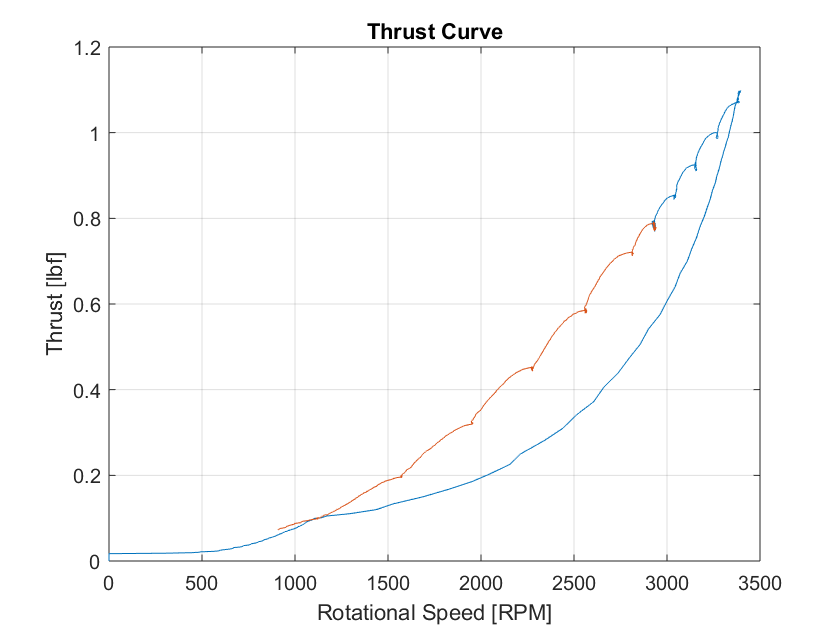

x = (1:2822);
y = (2823:5644);

figure(1)
plot(rot_speed_rpm(x), T(x), rot_speed_rpm(y), T(y)); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

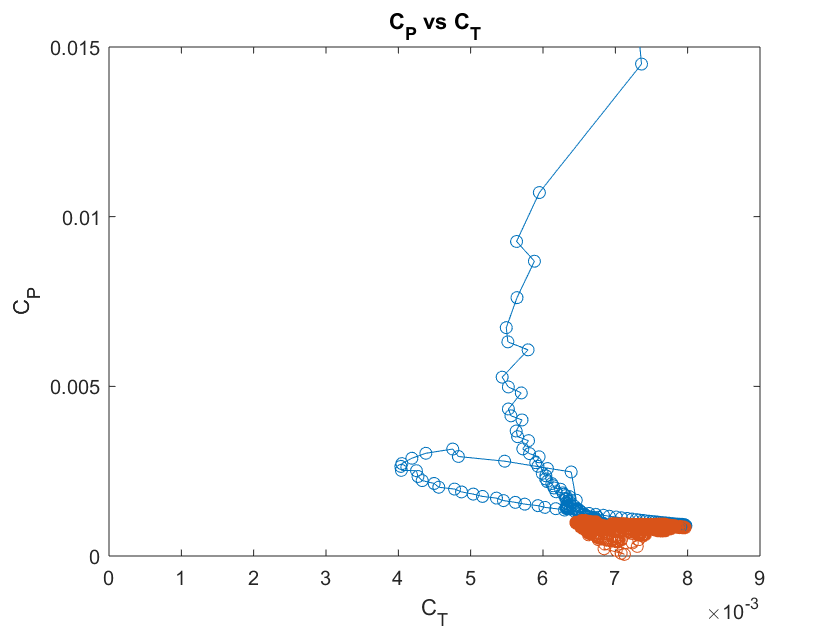


figure(2)
plot(C_T(x), C_P(x), 'o-', C_T(y), C_P(y), 'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P'); xlim([0,0.009]); ylim([0,0.015]);

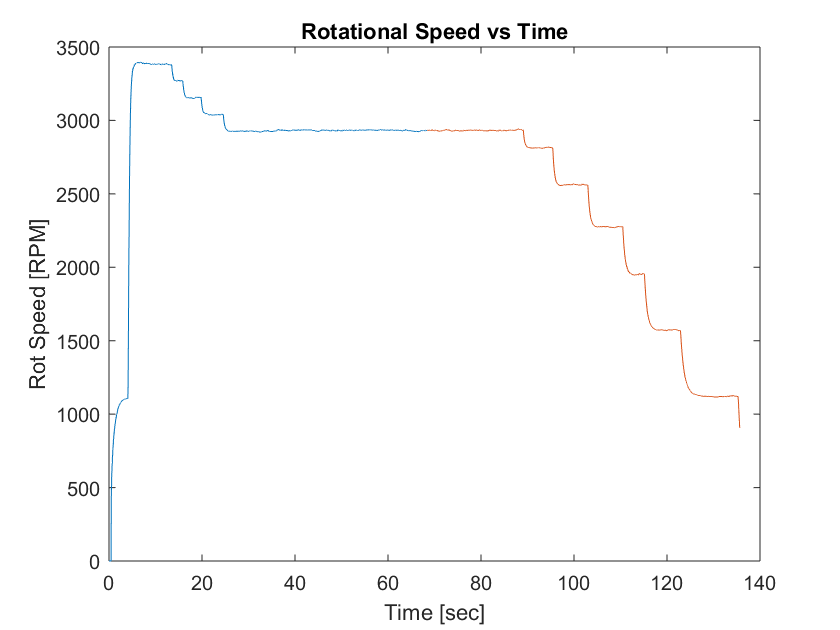


figure(3)
plot(time(x), rot_speed_rpm(x), time(y), rot_speed_rpm(y)); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]');

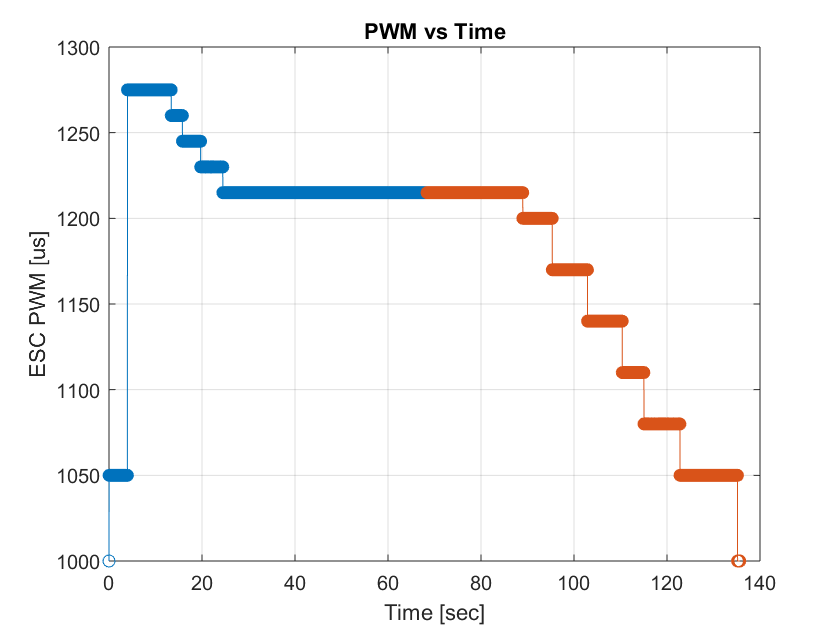




figure(4)
plot(time(x), PWM(x), 'o-', time(y), PWM(y), 'o-'); title('PWM vs Time'); 
xlabel('Time [sec]'); ylabel('ESC PWM [us]'); grid('on');

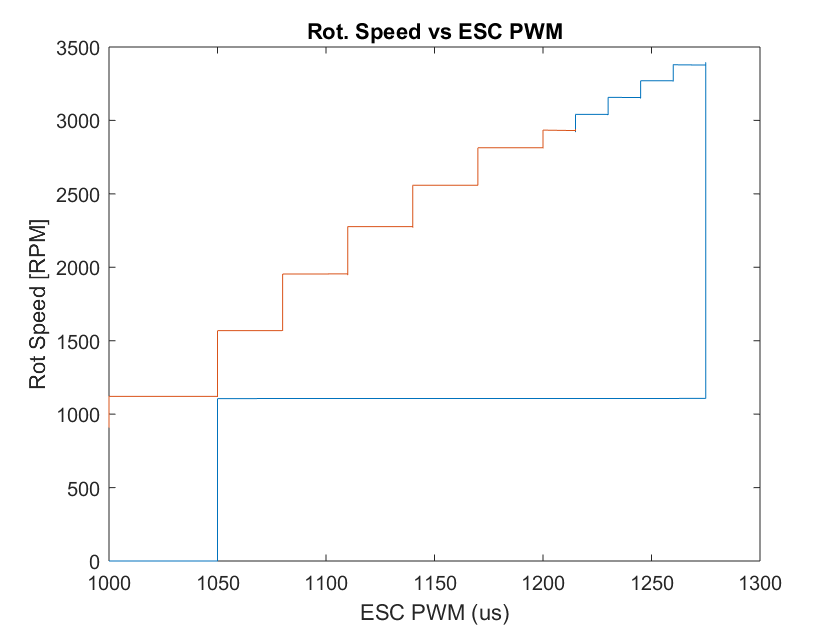




figure(5)
plot(PWM(x), rot_speed_rpm(x), PWM(y), rot_speed_rpm(y)); title('Rot. Speed vs ESC PWM'); 
xlabel('ESC PWM (us)'); ylabel('Rot Speed [RPM]');

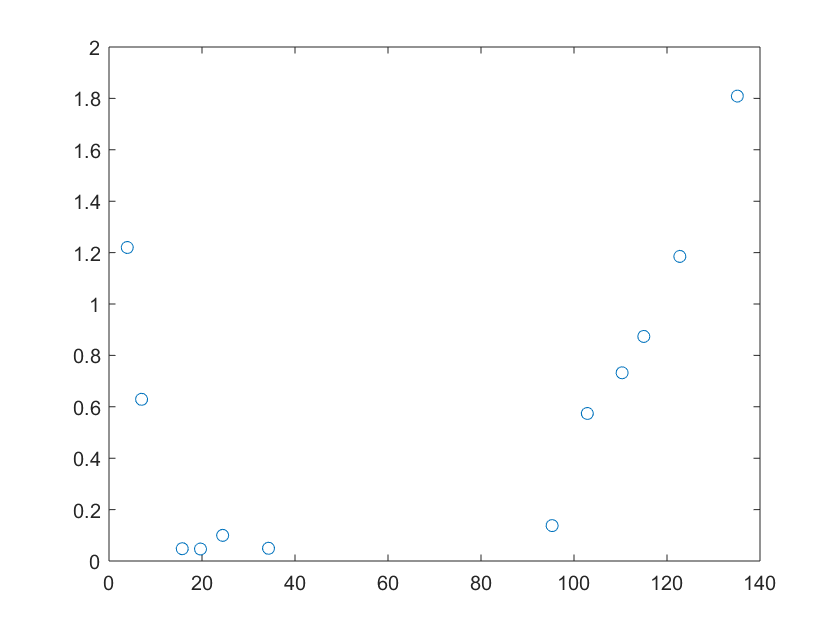



figure(6)
plot(time, Settling_time, 'o-');

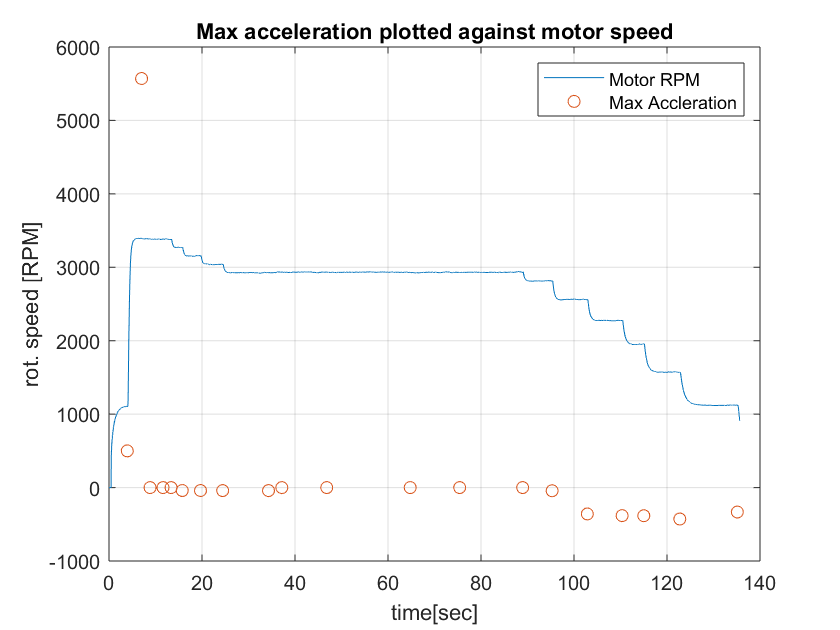


figure(7)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed');
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');